**Аппроксимировать функцию x=t*cos(2pi*t) на промежутке [−1; 1] двумя способами:**

**A. При помощи ортогональных многочленов Чебышёва I рода.**

**B. При помощи многочлена Тейлора (в точке t_0=0).**

**A. многочлены Чебышева 1 рода**

Инициализируем переменные

syms t
f  = t*cos(2*pi*t);
n  = 8;
norm0 = 1/sqrt(pi);
normk = sqrt(2/pi);
T = sym(zeros(1,n+1));
c = sym(zeros(1,n+1));

Строим полином и частичную сумму ряда

for k = 0:n
    Tk = chebyshevT(k,t);
    phi = (k==0)*norm0*Tk + (k>0)*normk*Tk;   
    T(k+1) = phi;
    c(k+1) = int( f*phi / sqrt(1-t^2), t, -1, 1 );  
end
Cheb_sym = sum(c .* T); 
Cheb_fun = matlabFunction(Cheb_sym, 'Vars', t);%переводим функцию из символьной в анонимную

**B. многочлен Тейлора**

строим многочлен

Taylor_sym = taylor(f, t, 'Order', n+1);
Taylor_fun = matlabFunction(Taylor_sym, 'Vars', t);%переводим функцию из символьной в анонимную

**Вычисляем апроксимацию вблизи нуля и равномерную апроксимацию**

 %переводим функцию в анонимный вид
points = [0.2, 0.1];
for tt = points
    nor = abs( double( subs(f, t, tt) ) - Cheb_fun(tt) );
    fprintf('|f(%.1f) - Cheb_8(%.1f)| = %.6f\n', tt, tt, nor);
end

|f(0.2) - Cheb_8(0.2)| = 0.069146
|f(0.1) - Cheb_8(0.1)| = 0.058641


for tt_points = [0.2 0.1]
    norm_p = abs( double( subs(f,t,tt_points) ) - Taylor_fun(tt_points) );
    fprintf('|f(%.1f) - Taylor_8(%.1f)| = %.6f\n', tt_points, tt_points, norm_p);
end

|f(0.2) - Taylor_8(0.2)| = 0.000030
|f(0.1) - Taylor_8(0.1)| = 0.000000


tt = linspace(-1, 1, 3);          
vals   = double( subs(f, t, tt) );
Cheb_vals = Cheb_fun(tt);
nor_sr  = max( abs( vals - Cheb_vals ) );
fprintf('max_{t∈[-1,1]} |f(t)-Cheb_8(t)| ≈ %.6f\n', nor_sr);

max_{t∈[-1,1]} |f(t)-Cheb_8(t)| ≈ 0.054683


norm_t = max( abs( vals - Taylor_fun(tt) ) );
fprintf('max_{t∈[-1,1]} |f(t)-Taylor_8(t)| ≈ %.6f\n', norm_t);

max_{t∈[-1,1]} |f(t)-Taylor_8(t)| ≈ 40.256632


(это я не поверила в расстояние=40,2)

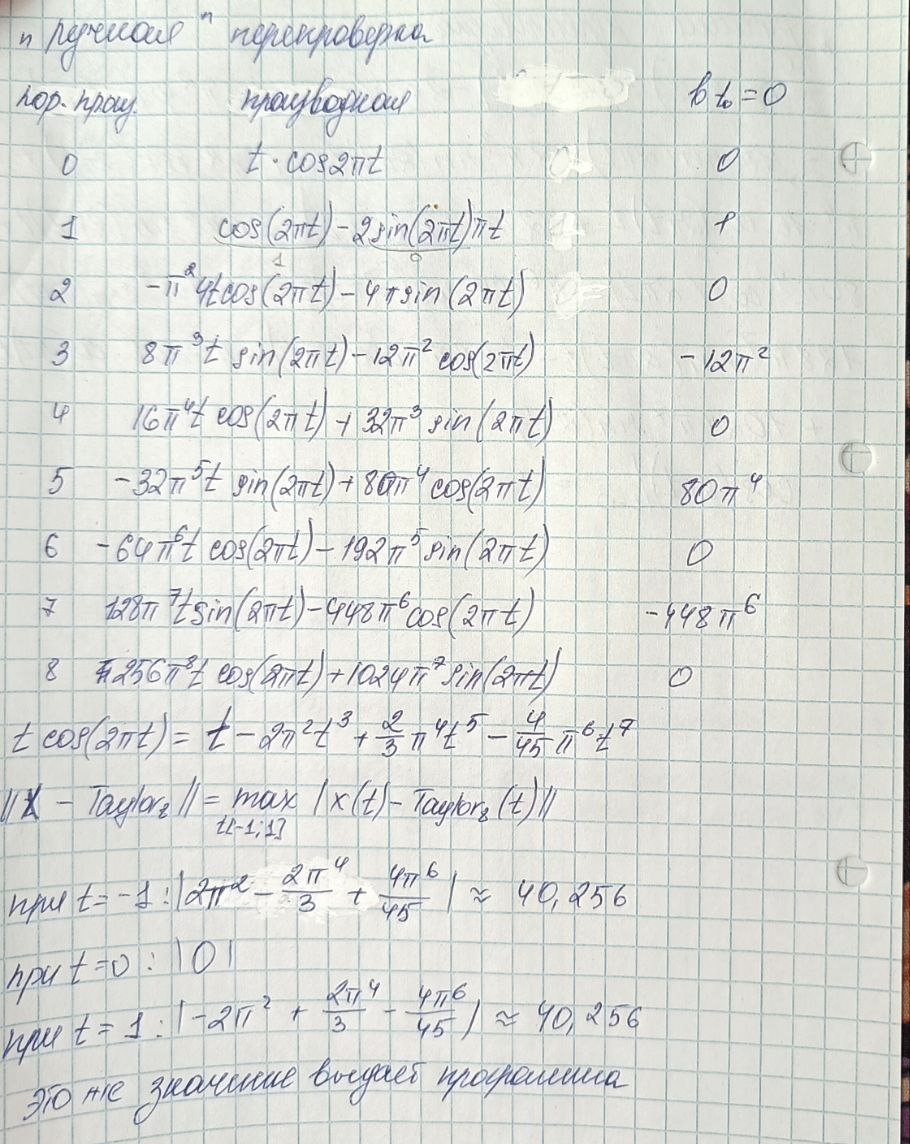

Следовательно, вблизи 0 значения многочлена Тейлора ближе к значениям функции х, чем значение апроксимации многочленами Чебышева. Но многочлены Чебышева дают более точную равномерную апроксимацию функции x.

Графики

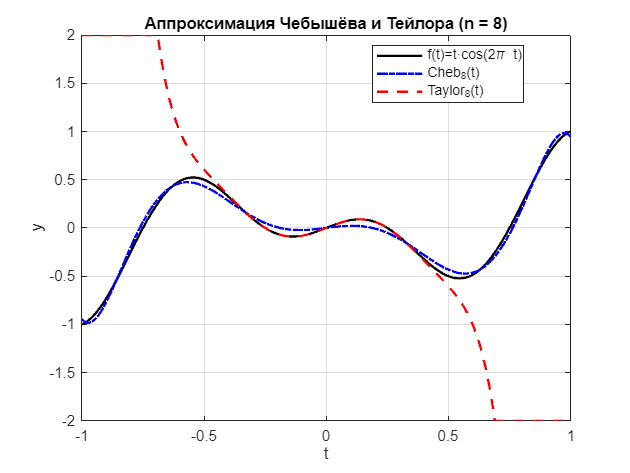

tt_plot = linspace(-1, 1, 1000);                 
f_plot     = double( subs(f, t, tt_plot) );      
Cheb_plot  = Cheb_fun(tt_plot);                 
Taylor_plot= Taylor_fun(tt_plot);               
clip = 2;                                    
Tay_clip = max( min(Taylor_plot,  clip), -clip);
plot(tt_plot, f_plot,    'k-', 'LineWidth',1.6); hold on
plot(tt_plot, Cheb_plot, 'b-.','LineWidth',1.6);
plot(tt_plot, Tay_clip,  'r--','LineWidth',1.6);   % Тейлор, но обрезанный, ибо иначе график очень сильно сжимается и ничего не понятно
hold off
axis tight                                  
legend('f(t)=t·cos(2\pi t)','Cheb_8(t)', sprintf('Taylor_8(t)',clip), 'Location','best');
xlabel('t'); ylabel('y');
title('Аппроксимация Чебышёва и Тейлора (n = 8)');
grid on

График подтверждает предположение, сказанное выше